Alejandro Armenta Arellano 

A017348789

Hacemos limpieza de variables y cerramos todo

clear all
close all
clc

Inicializamos las matrices de transformacion para los movimientos y declaramos las posicion inicial 

H0=SE3; 
H1=SE3(rotz(-pi/2), [0 0 0]); 
H2=SE3(rotx(pi/2), [0 0 2]);
H3=SE3(roty(-3/2*pi), [0 0 0]);  
H4=SE3(rotx(0), [2 0 0]);
H5=SE3(rotx(0), [2 0 0]); 
H6 = SE3(rotx(0), [2 0 0]); 

convertimos los movimientos realizados en variables para unirlos con posiciones anteriores

H20= H1*H2;
H30= H20*H3; 
H40 = H30*H4;
H50 = H40*H5;
H60 = H50*H6;

x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

Generamos el plano para las graficas 

plot3(x, y, z,'LineWidth', 1.5); axis([-1 5 -10 5 -1 10]); grid on;
hold on;
trplot(H0,'rgb','axis', [-1 6 -1 8 -1 4])

Para finalizar graficamos el punto inical y los movimientos

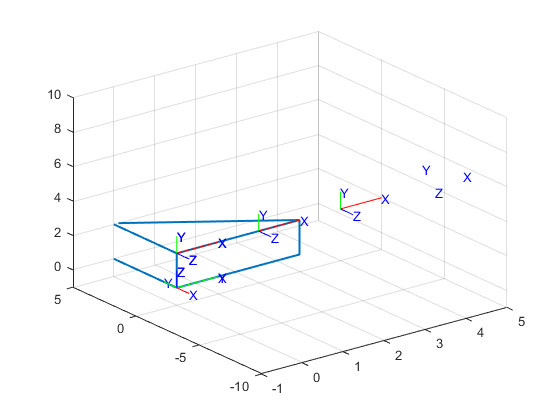


tranimate(H0, H1,'rgb','axis', [-1 6 -1 8 -1 4])
tranimate(H1, H2,'rgb','axis', [-1 6 -1 8 -1 4])
tranimate(H20, H30,'rgb','axis', [-1 6 -1 8 -1 4])
tranimate(H30, H40,'rgb','axis', [-1 6 -1 8 -1 4])
tranimate(H40, H50,'rgb','axis', [-1 6 -1 8 -1 4])
tranimate(H50, H60,'rgb','axis', [-1 6 -1 8 -1 4])

disp(H60)

    1         0         0         6
    0         0        -1         0
    0         1         0         2
    0         0         0         1
